% Clean up old progress bars
close all;

% Constant area
area_floor = 210; % m^2, average US home size 
height_aperture = 3;
width_aperture = 10;

% Parameters to sweep
floor_thicknesses = [0.1:0.1:1];
insulation_thicknesses = [0.10:0.02:0.20];

start_day = 61;
end_day = 180;
skip_days = 45;
timespan = [start_day, skip_days, end_day] * (24 * 60 * 60); % Convert date time ranges to seconds
max_timestep = 360; % 6min
ideal_temp = 20 + 273.15; % 20C is room temperature, in K

cumulative_errors = house_sweep(timespan, max_timestep, height_aperture, width_aperture, area_floor, floor_thicknesses, insulation_thicknesses, ideal_temp);

Running a parameter sweep with 60 simulations...


Done with sweep! Ran 60 simulations! Took 31.72 seconds (avg 0.52s each).


save(sprintf("simulation_results_%1.0f.mat", now()));

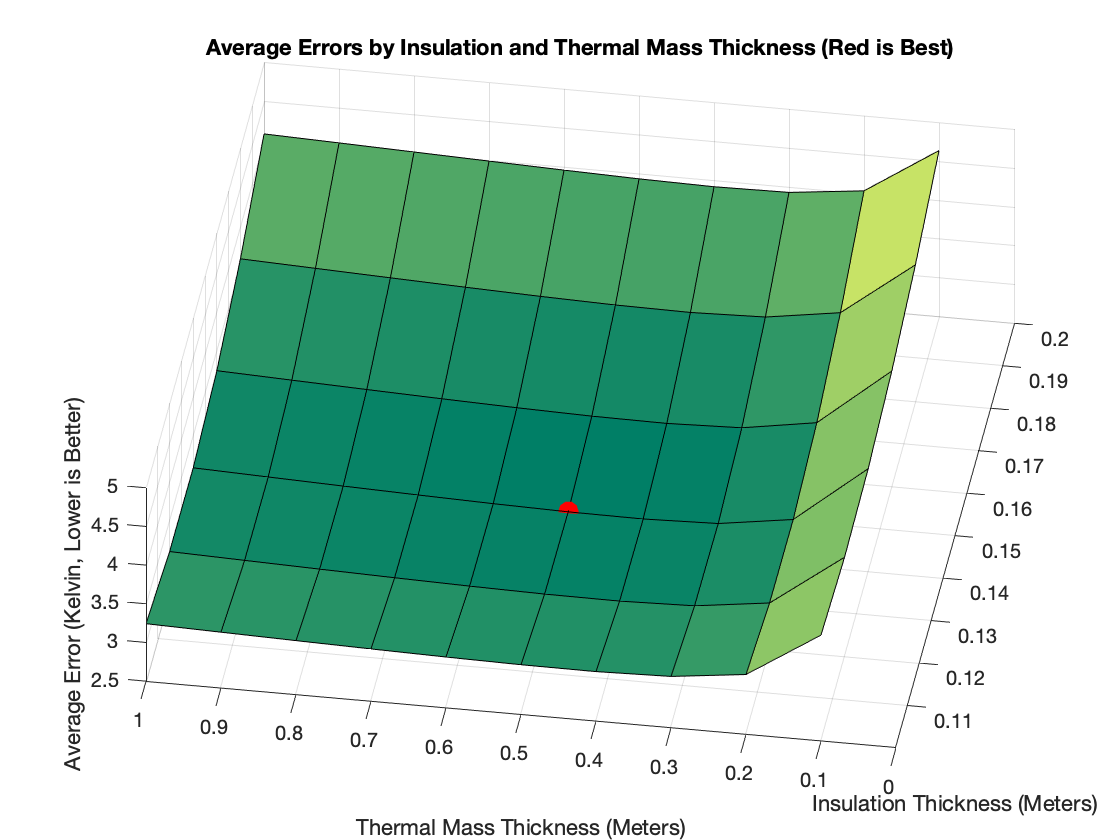

%% Plot the mesh
figure; clf;

scale_factor = 1; % convert from Kelvin-Seconds to Kelvin-Days

[x_axis, y_axis] = meshgrid(insulation_thicknesses, floor_thicknesses);
surf(x_axis, y_axis, cumulative_errors / scale_factor);

colormap summer; hold on;

title("Average Errors by Insulation and Thermal Mass Thickness (Red is Best)");
xlabel("Insulation Thickness (Meters)");
ylabel("Thermal Mass Thickness (Meters)");
zlabel("Average Error (Kelvin, Lower is Better)");

%% Plot the minimum point
% Find the minimum, then figure out its coordinates
[~, min_idx] = min(cumulative_errors, [], 'all', 'linear');

insulation_idx = floor(min_idx / size(cumulative_errors, 1)) + 1;
floor_idx = mod(min_idx, size(cumulative_errors, 1)) + 1;

plot3( ...
    insulation_thicknesses(insulation_idx), ...
    floor_thicknesses(floor_idx), ...
    cumulative_errors(floor_idx, insulation_idx) / scale_factor, ...
'r.', 'MarkerSize', 35, 'LineWidth', 5);

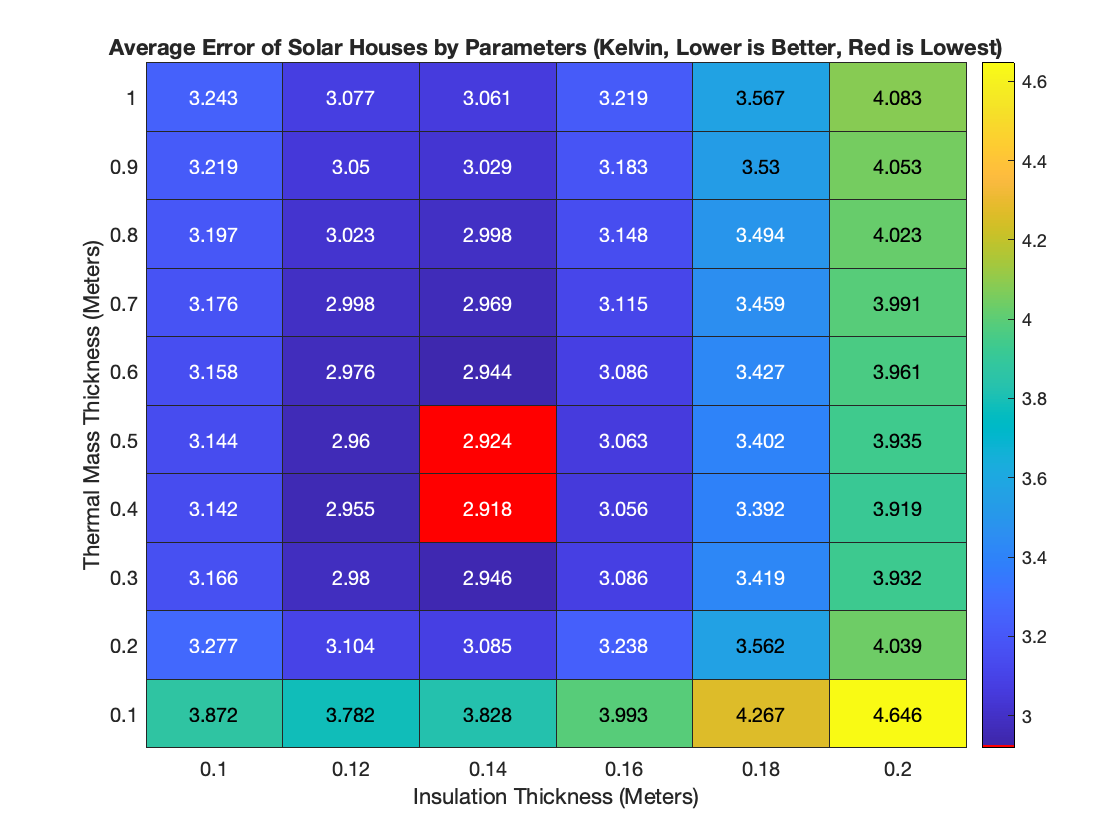


%% Plot the Heatmap
figure; clf;

h = heatmap(insulation_thicknesses, floor_thicknesses, cumulative_errors / scale_factor);
% By default, the lowest value isn't in the bottom left of the heatmap, so
% we flip the Y-axis.
h.YDisplayData = flip(floor_thicknesses);

xlabel("Insulation Thickness (Meters)");
ylabel("Thermal Mass Thickness (Meters)");
title("Average Error of Solar Houses by Parameters (Kelvin, Lower is Better, Red is Lowest)");

% We want the lowest (best) value to be a different color (specifically,
% red), so we switch to a specific color map that doesn't include red, then
% modify it to have red as the very lowest value.
colormap default;
colormap([1 0 0; colormap()]);